**Question 2**

We suppose that there are p students in a class each of whom must be allocated to work in a group on exactly one of *q* problems. Each student i has expressed a preference order for each problem j, taking values 1, 2, . . . , *q*, where 1 denotes the student’s top preference and *q* denotes their least favourite. Assume the preferences are provided in a *p×q* matrix $C_{i,j}$ . The binary decision variables $x_{i,j}$ indicate whether student *i* is matched to problem *j*, and can be unravelled as a vector *x*. We suppose that the objective is to minimise 


$$\frac{1}{p}\sum_{i,j} C_{\mathrm{ij}} x_{\mathrm{ij}}$$


i.e., the preference order of the problem actually allocated to each student, averaged over the class.

**a) Write down conditions on x that ensure each student is allocated to exactly one problem. Exhibit and explain Matlab code for use with intlinprog that builds the associated constraint matrix.**

To ensure each student is each assigned to one problem, p equality constraints are made of the general form:


$$\sum_{j=1}^q x_{p,j} =1$$


$C_{i,j}$ of the shape *p×q* is unravelled to form the vector *X* of the form:


$$X=\left\lbrack x_{1,1\;} ,{\;x}_{1,2\;} ,\cdots \;,{\;x}_{1,\;q-1} \;,\;x_{1,q} \;,{\;x}_{2,1} \;,\;x_{2,2} \;,\cdots {\;,\;x}_{p,\;q-1} \;,x_{p,q} \right\rbrack$$


The resulting $A_{\mathrm{eq}}$ and $b_{\mathrm{eq}}$ matrices take on the following form:

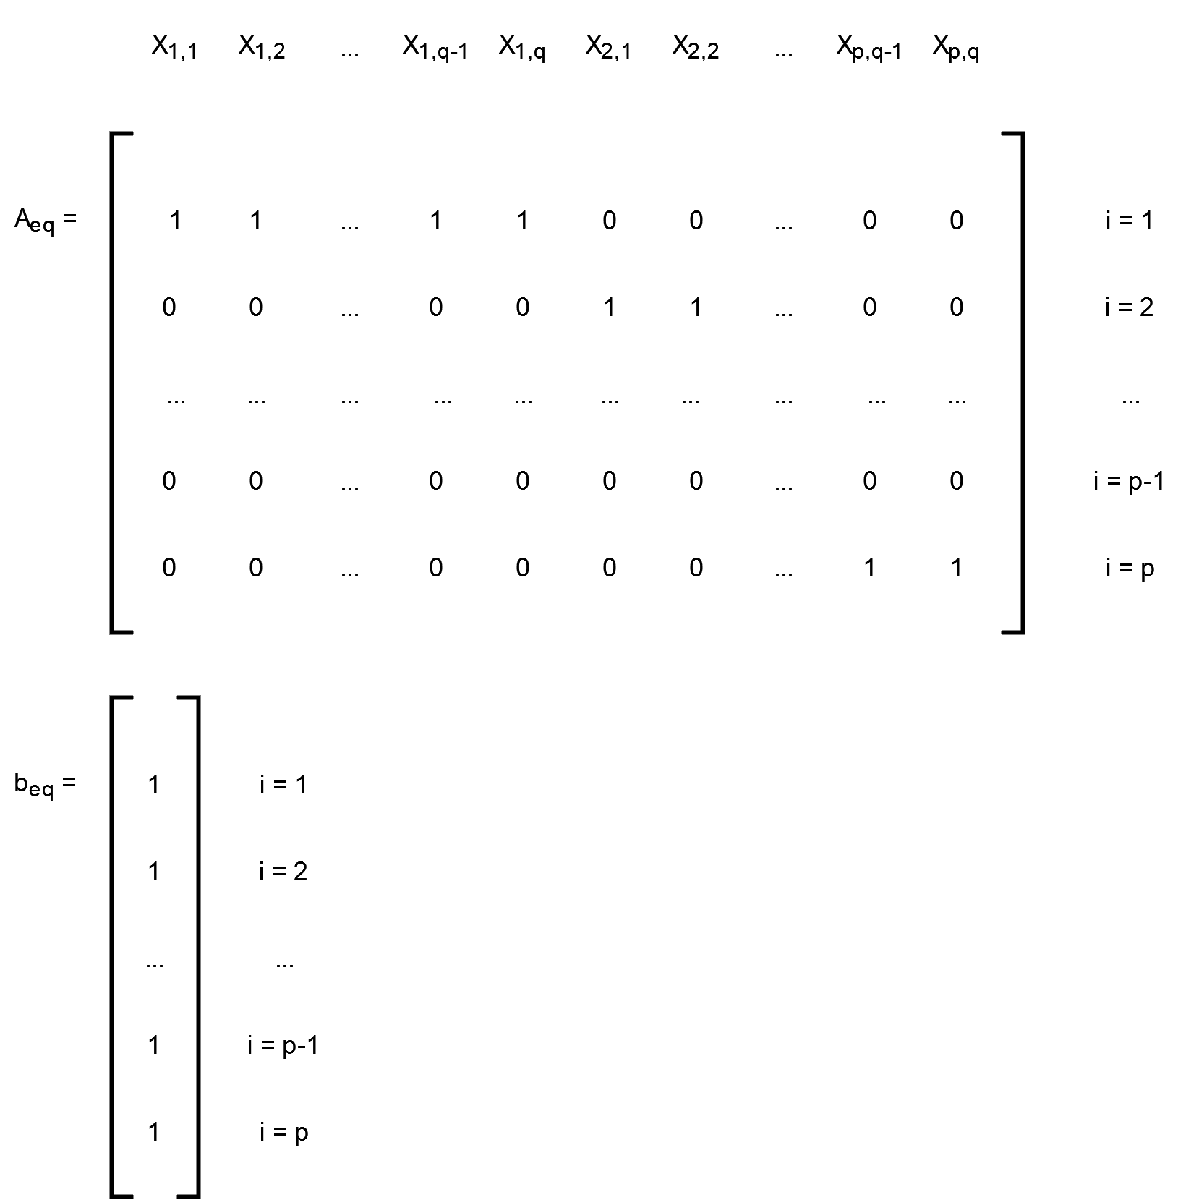

The application of these constraints in code is shown below

% Set up the problem variables
p = 5;
q = 2;

% Create a matrix template for the first student
A_circ = zeros(1, p*q);
A_circ(1:q) = 1

A_circ =      1     1     0     0     0     0     0     0     0     0


% Initialise Aeq and iteratively populate each new student row
Aeq = zeros(p, p*q);
Aeq(1, :) = A_circ;
for i = 1:p-1
    shift = q * i;
    row = circshift(A_circ, shift);
    Aeq(i+1, :) = row;    
end
Aeq

Aeq =      1     1     0     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     0     0     1     1


beq = ones(p, 1);
beq

beq =      1
     1
     1
     1
     1


% The values of each x variable are constrained to one by setting the lb, ub and intcon 
% inputs to intlinprog

% Enforces all results to be integer values
intcon = ones(p, 1);

% Enforces binary results
lb = zeros(p*q,1);
ub = ones(p*q, 1);


**(b) Write down conditions that ensure problem *****j***** has no fewer than **${\mathit{\mathbf{g}}}_{\min }$** and no more than **${\mathit{\mathbf{g}}}_{\max }$** students allocated to it, where **${\mathit{\mathbf{g}}}_{\min }$** and **${\mathit{\mathbf{g}}}_{\max }$** are non-negative integers. Exhibit and explain Matlab code for use with intlinprog that builds the associated constraint matrices.**

To ensure each group is assigned between $g_{\min }$ and $g_{\max }$ students, 2*×q* number of inequality constraints are made of the general forms:


$$\sum_{i=1}^p x_{i,q} \le g_{\max }$$



$$-\sum_{i=1}^p x_{i,q} \le {-g}_{\min }$$


Using the same unravelled form of $C_{\mathrm{ij}}$ outlined in part a, the following general inequality matrices *A*, and *B *can be formed:

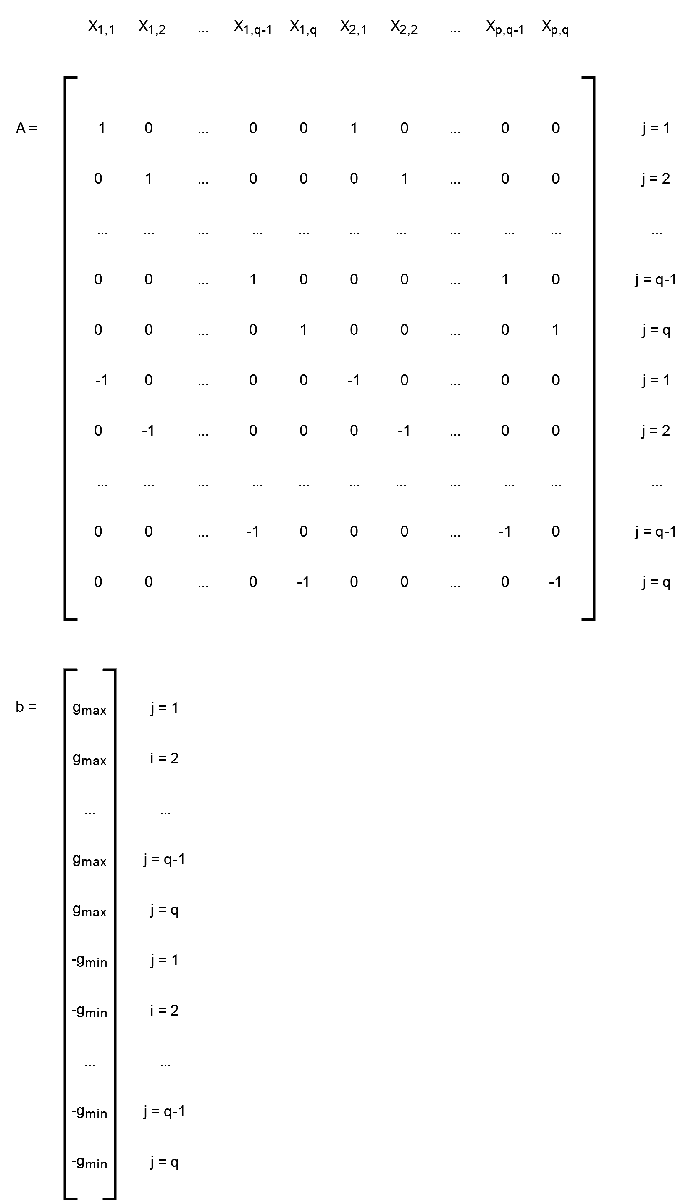

% Define gmax and gmin
gmax = 5
gmin = 3

% A can be built geometrically using eigen matrices and the repmat function
pattern = eye(q);
A1 = repmat(pattern, 1, q);
A2 = -A1;

b1 = zeros(q, 1);
b1(:,1) = gmax;

b2 = zeros(q, 1);
b2(:,1) = -gmin;

A = [A1; A2]
b = [b1; b2];
